# Divergence and Gradient Examples

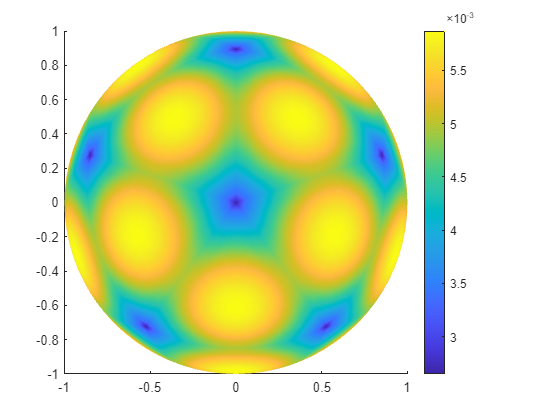

% Define spherical mesh and get basic features
[v,f] = equilateralMesh(20); 
[v,f] = increasePatch(v,f,16); 
v = v./vecnorm(v,2,2); 

fa = calcFaceArea(v,f); 
va = faces2verts(f,fa); 

faxis = @() cellfun(@feval, {@() axis('image','vis3d'), @() colorbar});

% figure; patchvfc(v,f,fa); faxis(); 
figure; patchvfc(v,f,va); faxis(); 

## Gradient

- Input should be scalar function on the vertices

- Output will be vector function on the faces

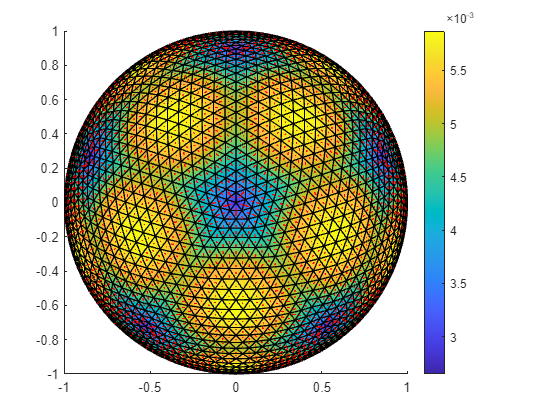

g = grad(v,f,va);
figure; patchvfc(v,f,va,'EdgeColor','k'); hold on; quiv3(verts2faces(f,v),g,'Color','r'); faxis();

% figure; multiplot(g, @(x) patchvfc(v,f,x), faxis);

% gv = faces2verts(f,g); 
% figure; multiplot(gv, @(x) patchvfc(v,f,x), faxis);
% figure; patchvfc(v,f,va,'EdgeColor','k'); hold on; quiv3(v,gv,'Color','r'); faxis();

## Divergence Examples

- Input should be vector valued function on the faces

- Output should be scala function on the vertices

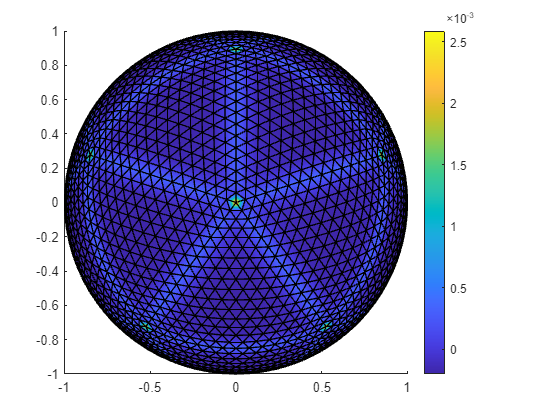

d = div(v,f,g); 
figure; patchvfc(v,f,d,'EdgeColor','k'); faxis(); 